การพยากรณ์ค่าระดับน้ำ (H) ที่สถานี S1 ในวันถัดๆ ไป เช่น Day 61 จนถึง Day 65

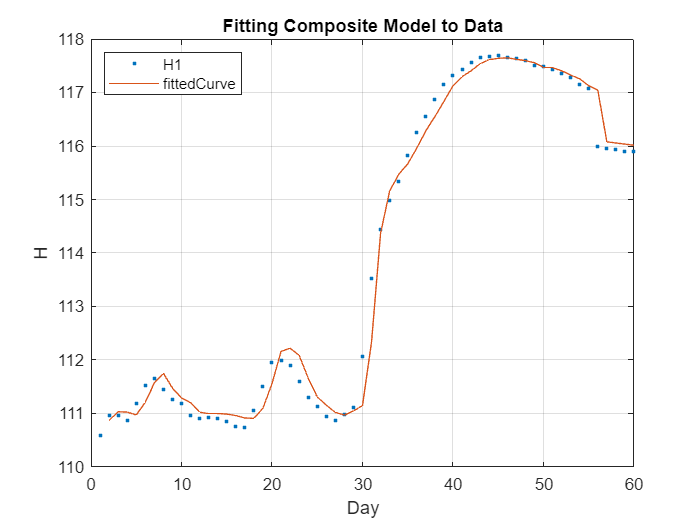

mdl = fittype('a*cos(x+f) + b*x^2 +c*x + d*log(x) + e','coefficients',{'a','b','c','d','e','f'},'independent','x','dependent','y');
fitResult = fit(H1(1:59),H1(2:60),mdl,'StartPoint',[0,0,0,0,0,1]);
coeffs = coeffvalues(fitResult);
a = coeffs(1);
b = coeffs(2);
c = coeffs(3);
d = coeffs(4);
e = coeffs(5);
f = coeffs(6);
nv = a * cos(H1(1:59)+f) + b * H1(1:59).^2 + c*H1(1:59) +d * log(H1(1:59)) + e;

plot(1:60,H1(1:60),'.')
hold on
plot(2:60,nv)
hold off
grid on
xlabel('Day');
ylabel('H');
title('Fitting Composite Model to Data');
legend({'H1','fittedCurve'},'Location','northwest');

Performance ของการ Fitting

R_squared = 1 - sum((H1(2:60) - nv).^2) / sum((H1(2:60) - mean(H1(2:60))).^2);
MAE = sum(abs(H1(2:60) - nv))/length(H1(2:60));
MSE = (sum((H1(2:60) - nv).^2))/(length(H1(2:60)));
fprintf('R_squared = %f\nMAE = %f\nMSE = %f', R_squared,MAE,MSE);

R_squared = 0.988494
MAE = 0.204786
MSE = 0.092787

Predict และแสดงค่า H ในวันถัดๆ ไป ของสถานี S1

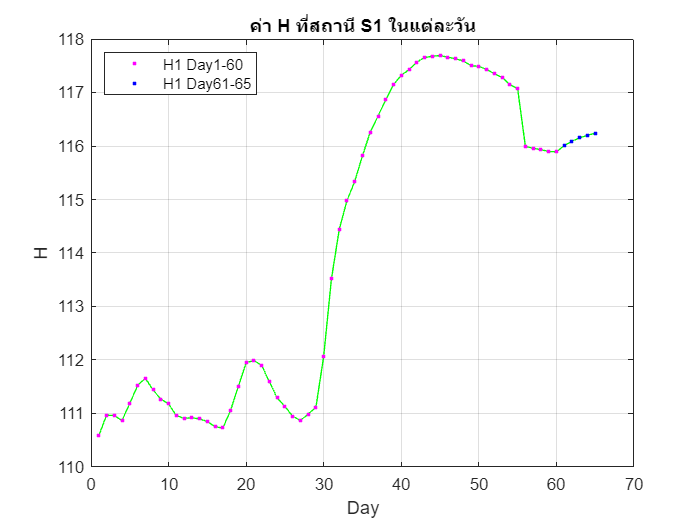

H1D61 = a * cos(H1(60)+f) + b * H1(60).^2 + c*H1(60) +d * log(H1(60)) + e;
H1D62 = a * cos(H1D61+f) + b * H1D61.^2 + c*H1D61 +d * log(H1D61) + e;
H1D63 = a * cos(H1D62+f) + b * H1D62.^2 + c*H1D62 +d * log(H1D62) + e;
H1D64 = a * cos(H1D63+f) + b * H1D63.^2 + c*H1D63 +d * log(H1D63) + e;
H1D65 = a * cos(H1D64+f) + b * H1D64.^2 + c*H1D64 +d * log(H1D64) + e;
H1 = [H1(1:60);[H1D61 H1D62 H1D63 H1D64 H1D65]'];

plot(1:65,H1,'g')
hold on
plot(1:60,H1(1:60),'m.');
plot(61:65,H1(61:65),'b.');
hold off
grid on
xlabel('Day');
ylabel('H');
title('ค่า H ที่สถานี S1 ในแต่ละวัน');
legend({'','H1 Day1-60','H1 Day61-65'},'Location','northwest');

fprintf('Day61: %.2f\nDay62: %.2f\nDay63: %.2f\nDay64: %.2f\nDay65: %.2f', H1(61),H1(65),H1(63),H1(64),H1(65));

Day61: 116.01
Day62: 116.24
Day63: 116.15
Day64: 116.20
Day65: 116.24